# Лабораторная работа №1

Метод Лагранжа для равномерной сетки

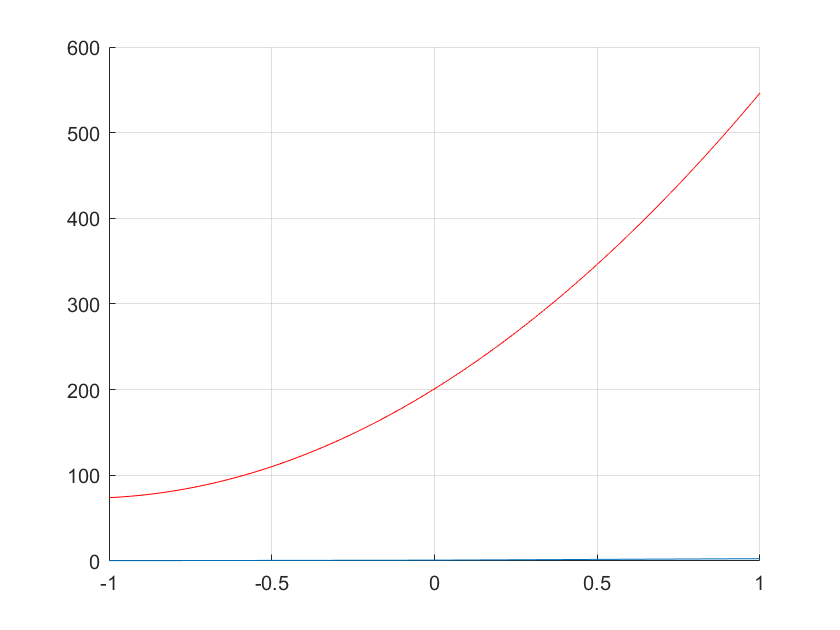

% x = linspace(-1, 1, 5);
x = [-1, 0, 1];
y = exp(x);
xx = -1:0.01:1;
yy = lagr(x, y, xx);
figure
hold on;
grid on;
plot(x, y);
plot(xx, yy, 'Color', 'red');

Построение зависимости ошибки от количества точек на равномерной сетке для непрерывной функции.

n_max = 100;
 
f = @(x) exp(-x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "rvn");
end

Analyzing and transferring files to the workers ...done.


disp('Равномерная сетка, непрерывная функция');

out

loglog(2:n_max, E(2:end));

Построение зависимости ошибки от количества точек на чебышевской сетке для непрерывной функции.

n_max = 10;
 
f = @(x) exp(-x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "cheby");
end
disp('Чебышевская сетка, непрерывная функция');
loglog(2:n_max, E(2:end));

Построение зависимости ошибки от количества точек на равномерной сетке для разрывной функции.

n_max = 20;
 
f = @(x) abs(x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "rvn");
end
disp('Равномерная сетка, разрывная функция');
loglog(2:n_max, E(2:end));

Построение зависимости ошибки от количества точек на чебышевской сетке для разрывной функции.

n_max = 10;
 
f = @(x) abs(x);
E = [];
parfor n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "cheby");
end
disp('Чебышевская сетка, разрывная функция');
loglog(2:n_max, E(2:end));

function y0 = lagr(x, y, x0)
    y0 = zeros(size(x0));
    for j = 1:length(x0)
        N = length(x);
        yx = 0;
        for i = 1:N
            y0 = y0 + y(i)*mlt(x0, x, i)/mltd(x, i);
        end
%         y0(j) = yx;
    end
end

function z = mlt(x0, x, j)
    z = 1;
    for i = 1:length(x)
        if i ~= j
            z = z.*(x0 - x(i));
        end
    end
end

function z = mltd(x, j)
    z = 1;
    for i = 1:length(x)
        if i ~= j
            z = z*(x(j) - x(i));
        end
    end
end

function delta = get_error(x_tr, x_pred)
    a = x_tr' - x_pred';
    a = abs(a);
    delta = max(a);
end

function eps = get_err_cont(f, dd, n, type_s)
    if type_s == "rvn"
        X = linspace(dd(1), dd(2), n);
        Y = f(X);
        xx = [];
%         for i = 2:length(X)
%             xx(i) = 0.5*(X(i)+X(i-1));
%         end
        xx = linspace(dd(1), dd(2), 100*n);
        yy = lagr(X, Y, xx);
        Y = f(xx);
        eps = get_error(Y, yy);
    elseif type_s == "cheby"
        syms t;
        X = solve(cos(n*acos(t)) == 0, 'Real', true);
        X = vpa(X);
        X = sort(X);
        Y = f(X);
        xx = [];
%         for i = 2:length(X)
%             xx(i) = 0.5*(X(i)+X(i-1));
%         end
        xx = linspace(dd(1), dd(2), 100*n);
        yy = lagr(X, Y, xx);
        Y = f(xx);
        eps = get_error(Y, yy);
    end
end